% Initialize %
image_dir = "images/Fruit";
%red_apples_pattern = 'appletree_ripe*.jpg';
%green_apples_pattern = 'appletree_raw*.jpg';
rotten_apples_filepattern = 'apples-rotten*.jpg';
apples_all_filepattern = 'apples*.jpg';

%images_all = Read_Images(image_dir, 'apple*.jpg');
rotten_apples_imgs = Read_Images(image_dir, rotten_apples_filepattern);

Reading images at - images\Fruit\apples-rotten*.jpg
Number of images found in directory: 2
Read 2/2


apples_all_imgs = Read_Images(image_dir, apples_all_filepattern);

Reading images at - images\Fruit\apples*.jpg
Number of images found in directory: 4
Read 4/4


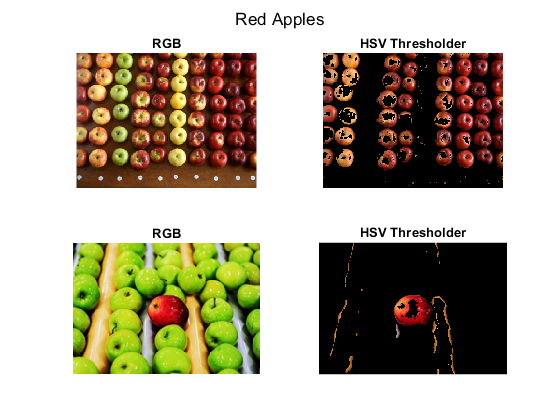

% remove first 2 images (rotten apples) from all list
apples_all_imgs = [apples_all_imgs(2+1:end)];

debug = false;
use_color_only_segm = true; % false (kcluster) works better for green apples in green backgrounds
store_results = false;


% Red Apples %
tic
nr_of_imgs = length(apples_all_imgs);
j = 1;

figure;
for i = 1:nr_of_imgs
    % resize the image so it runs faster
    resized_img = imresize(apples_all_imgs{i}, 0.5);
    
    [bw_red, red_apples_masked] = createRedApplesMask(resized_img);
    %red_clusters = KMeansCluster(resized_img, 3, debug);
    %red_apples_masked_kmeans = red_clusters{3};
    
    if (store_results == true)
        imwrite(red_apples_masked, "images/Fruit/Results/red_apples_result_" + i + ".png");
        %imwrite(red_apples_masked_kmeans, "images/Fruit/Results/red_apples_kmeans_result_" + i + ".png"); 
    end
    
    % PLOT %
    subplot(nr_of_imgs, 2, j);
    imshow(resized_img);
    title("RGB");
    subplot(nr_of_imgs, 2, j+1);
    imshow(red_apples_masked);
    title("HSV Thresholder");
    %subplot(nr_of_imgs, 2, j+2);
    %imshow(red_apples_masked_kmeans);
    %title("K-Means Cluster");
    
    j = j + 2;
end
sgtitle("Red Apples");

toc

Elapsed time is 0.456615 seconds.


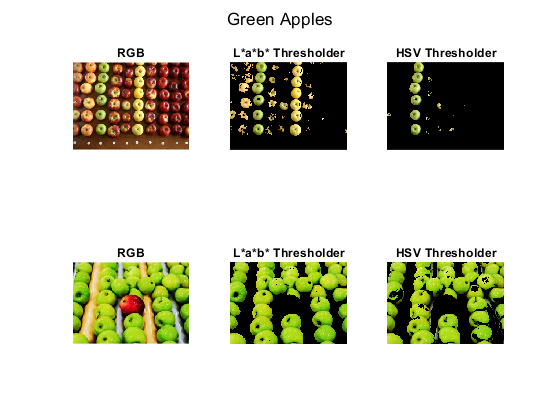


tic
% Green Apples %
j = 1;
figure;
for i = 1:nr_of_imgs
    % resize the image so it runs faster
    resized_img = imresize(apples_all_imgs{i}, 0.5);
    
    green_apples_masked_lab = createGreenApplesMask_lab(resized_img);
    [bw_hsv, green_apples_masked_hsv] = createGreenApplesMask_hsv(resized_img);
    %green_clusters = KMeansCluster(resized_img, 4, debug);
    %green_apples_masked_kmeans = green_clusters{1};
    
    % Store results
    if (store_results == true)
        imwrite(green_apples_masked_lab, "images/Fruit/Results/green_apples_lab_result_" + i + ".png");
        imwrite(green_apples_masked_hsv, "images/Fruit/Results/green_apples_hsv_result_" + i + ".png");
        %imwrite(green_apples_masked_kmeans, "images/Fruit/Results/green_apples_kmeans_result_" + i + ".png"); 
    end
    
    % PLOT %
    subplot(nr_of_imgs, 3, j);
    imshow(resized_img);
    title("RGB");
    subplot(nr_of_imgs, 3, j+1);
    imshow(green_apples_masked_lab);
    title("L*a*b* Thresholder");
    subplot(nr_of_imgs, 3, j+2);
    imshow(green_apples_masked_hsv);
    title("HSV Thresholder");
    %subplot(nr_of_imgs, 4, j+3);
    %imshow(green_apples_masked_kmeans);
    %title("K-Means Cluster");
    
    j = j + 3;
end
sgtitle("Green Apples");

toc

Elapsed time is 0.515278 seconds.


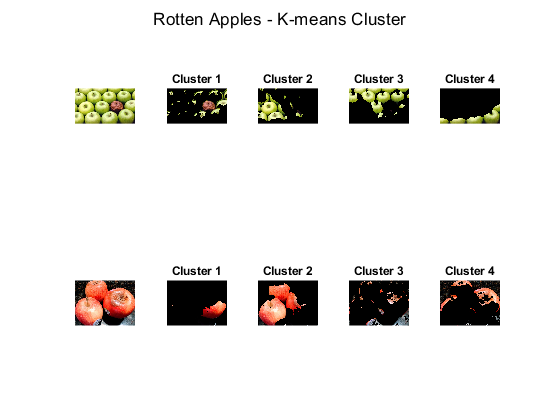


tic
% Rotten Apples %
figure;
j = 1;
nr_of_imgs = length(rotten_apples_imgs);
nr_of_clusters = 4;
nr_of_columns = nr_of_clusters + 1;
for i=1:nr_of_imgs
    rotten_clusters = KMeansCluster(rotten_apples_imgs{i}, nr_of_clusters, false);
    
    % PLOT %
    subplot(nr_of_imgs, nr_of_columns, j);
    imshow(rotten_apples_imgs{i});
    
    for cluster=1:length(rotten_clusters)
        subplot(nr_of_imgs, nr_of_columns, j+cluster);
        imshow(rotten_clusters{cluster});
        title("Cluster " + cluster);
    end
    
    j = j + nr_of_columns;
end
sgtitle("Rotten Apples - K-means Cluster");

toc

Elapsed time is 21.418946 seconds.
